# Haptic Click Track Pre-Processing Script

## Introduction

This is the haptic click track pre-processing script, used to generate a text file compatible with Max/MSP's *coll *object. The output of this script will allow you to output pulses on the Vibropixel at the correct time based on the audio click track you specify. This was written with the intent of allowing someone without much knowledge in MATLAB the ability to run and modify this script with the intent to create new haptic click track files without much difficulty. Use the run section button on each section one by one if this is the case. This script assumes you have a Vibropixel transmitter and reciever with the metronome firmware loaded and unmodified, and the associated Max patch (`hapticClickTrack-release-V1.0.maxpat`) that can then process the output of this script.

## Setup

First, specify the location of the audio file by modifying the string (the part in single quotes) with the location and running this section of code.

[audio, Fs] = audioread('../../../McGill Work/Fall 2016/Thesis Research/Haptic Metronome/Audio/Charge_Click_Voice_Advanced_test.wav');
audio = audio(:,1);

If you see a large matrix called audio and a number Fs in the workspace, this block of code is working. If not, you probably have an error in the string of the location of your audio.

Next, specify the file name of the TXT file you want to save the output as. You can also specify the location in which to save it to. It will save the file in the containing folder if no location is specified. Change only the first argument in single quotes for this section of code.

fileID = fopen('filename.txt','w');

After hitting run section, this should give you a value in the Workspace called fileID

Next, this section of code will modify some parameters of the Vibropixels to give some customization of the pulses. This section of code will modify things such as Vibropixel amplitude, base amplitude, etc... If you're not familiar with the Vibropixels, it's best to leave the default values specified here, otherwise you might run into difficulties.

 % Factor used to slow down tempo for rehersals. I.E.: Specify 0.5 for half speed.
scaleFactor = 1;   
% Device ID. 511 means this message will be received by all Vibropixels in the area. 
% Change only if you know how to change the device ID on the Vibropixel.
devID = 511;
% Message ID. Do not change unless you modified the Vibropixel firmware
messID = 30;
% Vibropixel rate.
rate = 15;
% Vibropixel amplitude.
amp = 150;
% Vibropixel base amplitude.
baseAmp = 50;
% Message for the icthus given by the big motor on the vibropixel.
% Should only really change this if you know what you are doing.
cylMotorMsg = '511 31 226 255 0 25 20 20;';

Now you should see all the values above in the workspace on the left. We're almost done with the setup. All that's left is to find the peaks in the audio click track. Running the next section of code will show a figure below it representing the audio click track. You can see little triangles all along the waveform, these are where the default setup of find peaks has found a peak. However, there should be one and only one triangle at the maximum of each click below. If you notice that there is more than one triangle on a click, or the triangle is missing on a click, change the value minClickHeight to be bigger or smaller, respectively. If the time between pulses is less than 500 samples, then you will need to change minClickDistance, than you need to lower that value (although I really don't think that will happen).

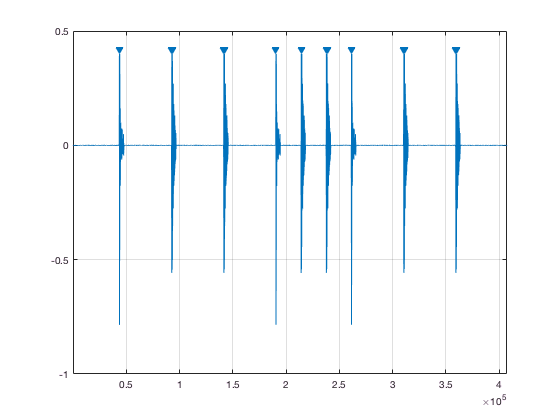

minClickHeight = 0.39;
minClickDistance = 500;
compAudio = min(audio, 0.4);
findpeaks(compAudio, 'MinPeakHeight', minClickHeight, 'MinPeakDistance', minClickDistance);

[pks, locs] = findpeaks(compAudio, 'MinPeakHeight', minClickHeight, 'MinPeakDistance', minClickDistance);

That's it for Setup.

## Main algorithm

If the setup is all correct, than you can just run the code section below and you should have a txt file you can open in the accompanying Max patch. There will be more information below if you are curious about what the algorithm is doing.

%Change rate value to one byte for Vibropixel transmission
if rate <= 1
    VPrate = round(sqrt(rate)*55);
else
    VPrate = round(sqrt(rate*800)+26);
end

%Initialize useful variables
VPclick = zeros(length(audio),1);
prevLoc = 0; %First location is start of file
index = 0;

% Generate the haptic click track message for each click found in audio
for i = 1:length(locs)
    % PART 1
    % Calculate attack and decay for the haptic click
    attack = (1/scaleFactor)*0.5*(locs(i)-prevLoc);
    if i+1 <= length(locs)
        decay = (1/scaleFactor)*0.5*(locs(i+1) - locs(i));
    else
        decay = (1/scaleFactor)*0.5*(length(audio) - locs(i));
    end
    
    % If attack in msecs less than 10 msecs, skip iteration 
    % (possible if non-click sounds occur at points, like someone saying "Attention please")
    if ((attack/Fs)*1000) < 100
        continue 
    end
    
    % If decay in msecs less than 10 msecs, skip iteration
    % (possible if non-click sounds occur at points, like someone saying "Attention please")
    if ((decay/Fs)*1000) < 100
        continue 
    end
    
    % PART 2
    % If it is the first time going through the loop,
    % Add a line to the file to turn on "metro mode" 
    % and determine time to wait before sending next message
    if index == 0
        VPdelay = 1000*(attack/Fs);
        fprintf(fileID,'%d%s %s %d %s\n', index,',', '1', devID, '33;');
        index = index+1;
    end
    
    % Find envelope length from attack and decay
    envLen = attack + decay;
    % Determine percentage of overall envelope length
    % for attack and decay (for transmission as byte)
    VPattack = floor(100*(attack/envLen));
    VPdecay = floor(100*(decay/envLen));
    
    % Calculate envelope length in msecs and then create 2 bytes to transmit
    VPenvLen = round((envLen/Fs)*1000);
    VPenvLenByteMultiplier = floor(VPenvLen/255);
    VPenvLenByteRemainder = (mod(VPenvLen, 255));
    
    % PART 3
    % Write small motor envelope message to file
    fprintf(fileID,'%d%s %f %d %d %d %d %d %d %d %d %d%s\n', index,',', VPdelay, devID, messID, VPrate, amp, VPenvLenByteMultiplier, VPenvLenByteRemainder, VPattack, VPdecay, baseAmp, ';');
    index = index+1;
    % PART 4
    % Determine time to wait before starting cylindrical motor
    VPdelay = VPdelay + 1000*(attack/Fs);
    % Write cylindrical message to file
    fprintf(fileID, '%d%s %f %s\n', index,',', VPdelay, cylMotorMsg);
    index = index+1;
    % Determine time to wait before small motor is triggered again
    VPdelay = VPdelay + 1000*(decay/Fs);
    % Store previous peak location
    prevLoc = locs(i);
end

% Write message to turn off "metro mode"
fprintf(fileID,'%d%s %f %d %s\n', index,',', VPdelay, devID, '33;');
index = index+1;
% Write message to stop Max patch mechanism
fprintf(fileID, '%d%s', index, ', stop;');
fclose(fileID);

This section explains the reasoning about some of the code above, particularly, the main `for` loop. 

From interviews with Guillaume Bourgogne, conductor and director of the McGill Contemporary Music Ensemble, we determined that there should be some ramp up and ramp down to the haptic click, to give the conductor a sense of anticipation for each beat. However, the peak of the haptic click should be at the point in time where the audio click occurs. This means that the motor should begin the ramp up before the audio click occurs in time, and therefore between two clicks. The following figure illustrates where the small motor messages should be transmitted to the Vibropixel.

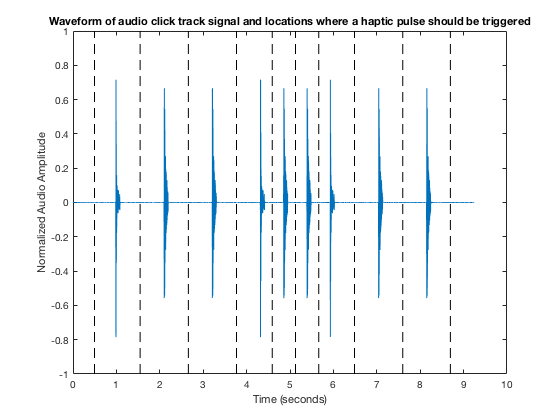

**Figure 1: **Waveform of the audio click track and the locations where a haptic pulse should be triggered.

We can also see from the above figure that the length of time for attack and decay are not always equal. If there is a shift in tempo to something faster, the attack will be longer than the decay. Likewise if the tempo shifts to something slower, the attack will be shorter than the decay. This is generalizable as:


$$Length_{Attack} = \frac{1}{2}(peak_i - peak_{i-1})$$



$$Length_{Decay} = \frac{1}{2}(peak_{i+1} - peak_{i})$$


This is what is being calculated by the commands beneath PART 1 in the code above. 

In PART 2, the first pass of the loop writes the first line in the .`txt` file that follows the `coll `standard. If you didn't change any of the defaults, this will be in the form:

`0, 1 511 33;`

The first number is the index which we use in the Max patch to go forward or backward in the `coll`, the next number is a timestamp value which is used in the Max patch to know at what point in time to transmit the Vibropixel message, and the last bytes are the Vibropixel message itself. In this case, it only tells the Vibropixel to start the "Metronome mode" which prevents turning off the small motor completely.

Similarly, in PART 3, the script would write the next line, which would be (for our default example):

`1, 494.829932 511 30 136 150 4 32 47 52 50;`

Now we see that the message should be sent out 495 msecs from the start. The last bytes are still the Vibropixel message, albeit much longer. The reason why we wait 495 msecs can be seen in Fig. 1, we need to wait half the time between the start of the file and the first audio click before triggering the haptic pulse. The Vibropixel message contains all the values necessary to produce the haptic pulse with the small motor on the Vibropixel. The next message written (PART 4) is to provide the ictus at the click point using the bigger faster cylindrical motor. It is of the form:

`2, 988.730159 511 31 226 255 0 25 20 20;`

This message should be sent out around 988 msecs, this is where the first click in figure 1 occurs. This triggers the cylindrical motor for a very short amount of time, providing an ictus at the point in time where the audio click would normally occur. We then compute the timestamp for the next message, and continue the loop. Once the loop is done, we write a message to turn off the "Metronome mode", after the decay of the last haptic pulse has passed. We write an additional line that will stop the Max patch from restarting the click track from the beginning.  

## Conclusion

If all the sections of this script have run, then you should have a `.txt` file with the name you specified, in the directory containing this script. If you have any issues running this script or questions, send an email to Patrick Ignoto at [patrick.ignoto@gmail.com](mailto:patrick.ignoto@gmail.com).